# Removing unwanted cat meouws from a sound recording

## 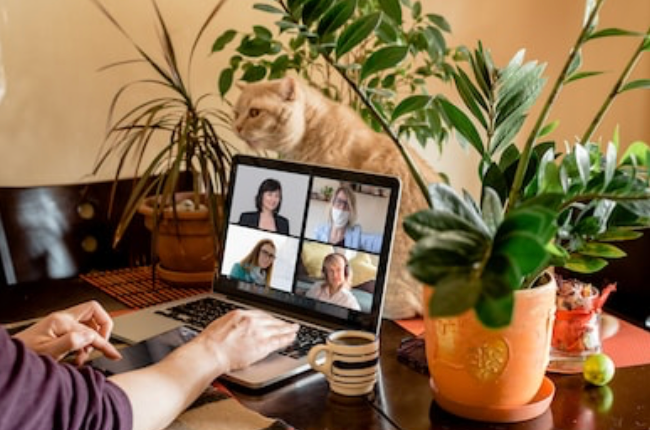

Note: Press the button 'Run section' in the live editor tab to sequencially run the code provided below at each section.

## Introduction

People who have cats know it: it is annoying to prepare video recordings when the cat is around since it might meouw during the recording and it is embarrasing to hear it during a remote video call.  

This live script explains how to remove an unwanted cat meouw from a recorded video using the Discrete Fourier Transform (DFT). The idea is that a cat meouw sound should contain high frequency content (which is probably why it is so annoying to most people), which can be filtered out from a regular voice recording whose main content is contained at lower frequencies (especially if it is a male's voice recording).

## Reading the signals and computing the DFT

Let us start with a given pre-recording and several meouw sounds which will be added to the pre-recording. Artificially adding these two signals is just carried out for convenience, since this will allow us to illustrate some concepts. You can have a real recording where the cat actually meouwed during the recording.

[Yvoice, FS]           = audioread('Recording.mp4'); % both are sampled att Fs = 44100 Hz

Error using audioread>readaudio (line 161)
The filename specified was not found in the MATLAB path.

Error in audioread (line 154)
    [y, Fs] = readaudio (filename, fileNameObj.RemoteFileName, range, datatype);

[Ymeouw, ~]            = audioread('Meouw.mp4');
Nsamplesvoice          = size(Yvoice,1);
Nsamplesmeouw          = size(Ymeouw,1);
Nsamples               = min(Nsamplesvoice,Nsamplesmeouw);
Yvoiceandmeouw         = Yvoice(1:Nsamples,:)+Ymeouw(1:Nsamples,:); % note that when importing an mp4 signal two components are imported (stereo). We will work with just the first signal Y(:,1)
audiowrite('RecordingandMeouw.mp4',Yvoiceandmeouw,FS);
p = audioplayer(Yvoiceandmeouw, FS);
play(p);

The hypothesis here is that the frequency content of the cat's meouw signal for high frequencies is much more significant than that of the sound recording. Let us have a look at the frequency content of both signals by ploting their DFTs.

FFTYvoice = fft(Yvoice(1:Nsamples,1));
FFTYmeouw = fft(Ymeouw(1:Nsamples,1));
omega = (0:length(FFTYmeouw)-1)/length(FFTYmeouw)*(2*pi); 
plot(omega,abs(FFTYvoice)), xlabel('Frequency \omega'), ylabel('absolute value of DFT male voice') 
plot(omega,abs(FFTYmeouw)), xlabel('Frequency \omega'), ylabel('absolute value of DFT cat meouw') 


The x axis (number of samples) of the Discrete Fourier Transform is plotted on a scaled axis (from $0$ to $2\pi$) that shows the Discrete Fourier Transform. It is clear from this plot that most of content of the human voice recorded signal, lines in the interval $[0,c]$ , $c=\frac{1}{5}$ whereas for the second signal (cat meouws) a very significant energy content belongs to the interval $[c,1]$. 

## Filtering

First, lets see if the male voice is still understandable if we remove the frequency content in the interval $[c,\pi]$.

FFTYvoice      = fft(Yvoice(1:Nsamples,1));
Nsamplesmeouw  = length(FFTYmeouw);
cutofffreq     = 1/5;
NFFTtruncate   = round(cutofffreq*1/(2*pi)*Nsamples);
FilteredFFT    = FFTYvoice.*[ones(NFFTtruncate,1);zeros(Nsamples-2*NFFTtruncate,1); ones(NFFTtruncate,1)]; % filter by multiplying by one the DFT at the wanted frequencies and by zero at the unwanted
Yvoicefiltered = ifft( FilteredFFT,'symmetric' ); % type help ifft to understand why the use of the optimal 'symmetric'
plot(omega,abs(FilteredFFT)), xlabel('Frequency \omega'), ylabel('Filtered DFT male voice') 
p = audioplayer(Yvoicefiltered, FS);
play(p);

compare with


pause(1)
p = audioplayer(Yvoice, FS);
play(p);

The high frequency sounds were removed but one can still understand the message! For instance the high frequency 'hi' is much lower frequency now. 

Let us now see the effect of removing the same frequency content from the meouw sounds.

FFTYmeouw           = fft(Ymeouw(1:Nsamples,1));
FilteredFFTmeouw    = FFTYmeouw.*[ones(NFFTtruncate,1);zeros(Nsamples-2*NFFTtruncate,1); ones(NFFTtruncate,1)];
Yvoicefilteredmeouw = ifft( FilteredFFTmeouw,'symmetric' );
plot(omega,abs(FilteredFFTmeouw)), xlabel('Frequency \omega'), ylabel('Filtered meouw signal')
p = audioplayer(Yvoicefilteredmeouw(1:Nsamples,1), FS);
play(p);

% compare with
pause(1)
p = audioplayer(Ymeouw(1:Nsamples,:), FS);
play(p);

The meouw sounds are almost gone! We are ready to filter the signal of the voice recording with the meouw sounds. We expect to get very good results: after all, due to linearity we should hear the sum of two filtered signals.

FFTYvoiceandmeouw      = fft(Yvoiceandmeouw(1:Nsamples,1));
FilteredFFTvoiceandmeouw   = FFTYvoiceandmeouw.*[ones(NFFTtruncate,1);zeros(Nsamplesmeouw-2*NFFTtruncate,1); ones(NFFTtruncate,1)];
Yvoicefilteredvoiceandmeouw = ifft( FilteredFFTvoiceandmeouw,'symmetric' );
plot(omega,abs(FilteredFFTvoiceandmeouw)), xlabel('Frequency \omega'), ylabel('absolute value of filtered DFT of males voice+meouws')
p = audioplayer(Yvoicefilteredvoiceandmeouw(1:Nsamples,1), FS);
play(p);


## Suggestions for follow-up work and variations

- The filter was designed in a very clumbsy manner. Can you do better, say by using low pass, band-pass, noise-supression filters (google these terms)?

- What would change if instead of given the recordings one would have to do this almost in real-time (think about a Skype call)?

- Think creatively about other applications where you would want to remove sounds and share the difficulties/challenges in applying similar frequency domain ideas.

- If you are a cat lover, you want to remove the human sound from the recording. How to go about doing that?